% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=x-2*pi; T=2*pi; [0;pi]
% Continue f(x) on a segment [-pi;0]
% 1) in an even way 
% 2) in an odd manner

clear
pi1=pi;
syms x real;
syms pi;
% 1)
f(x)=piecewise(-pi<x<=0,pi+2*x,0<=x<pi,pi-2*x)

$$f(x) = \left\{ \begin{array}{cl} 2\,x+\pi & \text{ if }x\in \left(-\pi ,0\right]\\ \pi -2\,x & \text{ if }x\in \left[0,\pi \right) \end{array}\right.$$


syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = 0$$

$$a(m) = -\frac{4\,{\left(-1\right)}^{m}-4}{m^{2}\,\pi }$$

$$b(m) = 0$$

$$abf(m) = -\frac{\cos\left(m\,x\right)\,\left(4\,{\left(-1\right)}^{m}-4\right)}{m^{2}\,\pi }$$

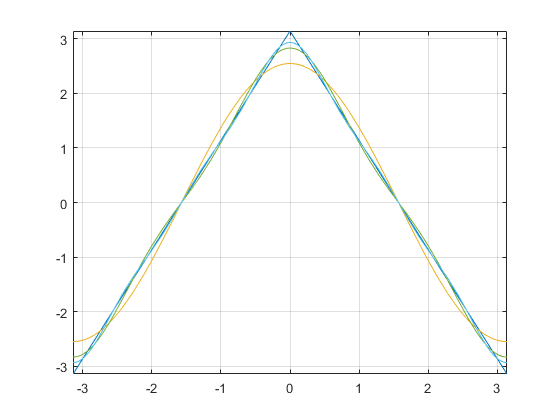


fplot(f(x),[-pi1 pi1]);
grid on
hold on

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi1 pi1])
    grid on
end
hold off


a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & \frac{8}{\pi } & 0 & \frac{8\,\cos\left(x\right)}{\pi }\\ 2 & 0 & 0 & 0\\ 3 & \frac{8}{9\,\pi } & 0 & \frac{8\,\cos\left(3\,x\right)}{9\,\pi }\\ 4 & 0 & 0 & 0\\ 5 & \frac{8}{25\,\pi } & 0 & \frac{8\,\cos\left(5\,x\right)}{25\,\pi } \end{array}\right)$$

% [ 1,      8/pi, 0,        (8*cos(x))/pi]
% [ 2,         0, 0,                    0]
% [ 3,  8/(9*pi), 0,  (8*cos(3*x))/(9*pi)]
% [ 4,         0, 0,                    0]
% [ 5, 8/(25*pi), 0, (8*cos(5*x))/(25*pi)]
